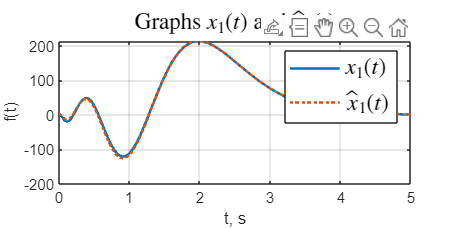

open_system('task_3_sim');
set_param('task_3_sim/x_', 'VariableName', 'x_')
set_param('task_3_sim/x', 'VariableName', 'x')
set_param('task_3_sim/e', 'VariableName', 'e')
set_param('task_3_sim/u', 'VariableName', 'u')
set_param('task_3_sim/y', 'VariableName', 'y')

out = sim('task_3_sim');

figure('Position', [100 100 800 400])
plot(out.x.Time, out.x.Data(:,1),'-', 'LineWidth',1.5)
hold on
plot(out.x_.Time, out.x_.Data(:,1),':', 'LineWidth',1.5)
%plot(out.y3,'-.', 'LineWidth',1.5)

grid()
title('Graphs $x_1(t)$ and $\hat{x}_1(t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$\hat{x}_1(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%yticks([0 1 2 3 4 5 6 7 8 9 10 11 12 13 14])
hold off

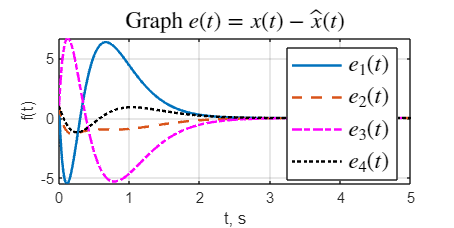


plot(out.e.Time,out.e.Data(:,1),'-', 'LineWidth', 1.5)
hold on
plot(out.e.Time,out.e.Data(:,2),'--', 'LineWidth', 1.5)
plot(out.e.Time,out.e.Data(:,3),'m-.', 'LineWidth', 1.5)
plot(out.e.Time,out.e.Data(:,4),'k:', 'LineWidth', 1.5)

grid("on")
title('Graph $e(t)=x(t) - \hat{x} (t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$e_1(t)$', '$e_2(t)$', '$e_3(t)$', '$e_4(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
%ylim([-7 1])
hold off

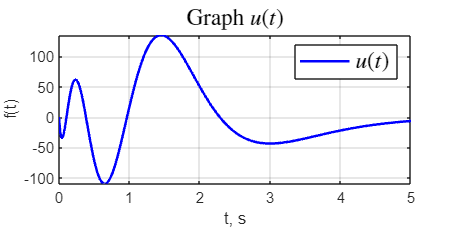



plot(out.u.Time, out.u.Data,'b', 'LineWidth', 1.5)
%hold on

grid("on")
title('Graph $u(t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$u(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')

%ylim([-7 1])
%hold off



